# **Lab 2. Asymptotic analysis**

Through this lab we will assess how the parameters estimation error $\left\|\theta^0 -\hat{\theta \;} \right\|$ is affected by the increase in the size of data used for the identification process. We will first consider an ideal case, where the system belongs to the same family of the model chosen for the identification, and then we will consider the case where the system does not belong to the same family of the chosen model.

## 1. Identifying an ARX system with an ARX model

We start by estimating an ARX system using an ARX model, in order to show that the estimation error will always decrease when we progressively increase the size of the dataset used for training the model.

clc, clearvars

### 1.1. Generating the system to identify

We choose the sampling time, we create the time vector and we retrieve the maximum dimension of data.

% Sampling time
Ts = 0.01;

% Time vector
t = (0:Ts:(10000*Ts))';

% Data dimension
Nmax = length(t);

Then we generate the system we want to identify using the `zpk` function, which return the continuous transfer function of the system by giving in input the zeros, the poles and the static gain of the system.

% Continuous transfer function
G = zpk(10, [-20, -20, -50, -100], -400*50*10);

Since the data acquisition process is discrete, we need to discretize the transfer function of the system.

% Discretization of the transfer function
Gz = c2d(G,Ts);

Let's see how the discrete system behaves through its impulse response.

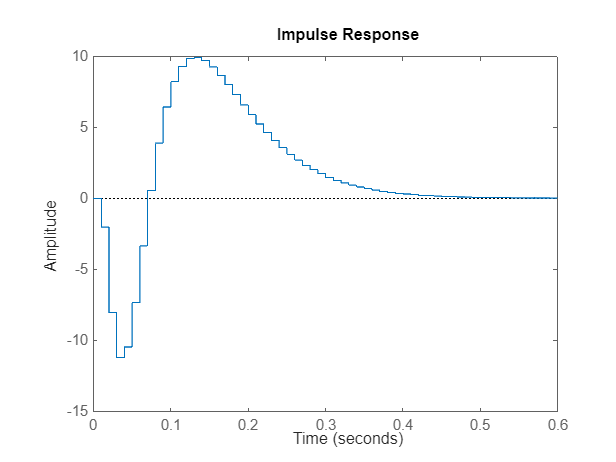

% Impulse response
figure(1), impulse(Gz)

We can see a negative peak at the beginning of the impulse response, which is a typical behaviour in non-minimal phase systems, i.e. systems with a positive zero (indeed we have 10 as a zero). We also notice that there is a small delay between the input and the output and that there is an important overshoot that goes to steady state after a few time instants.

### 1.2. Tweaking the parameters of the system

We extract the numerator and denominator coefficients from the transfer function using the command `tfdata`.

% Extracting coefficients
[num,den] = tfdata(Gz,'v')

num =          0   -0.0204   -0.0273    0.0476    0.0083


den =     1.0000   -2.6119    2.4890   -1.0185    0.1496


Then we tweak the parameters of the system rounding them up in order to better appreciate the quality of the estimates.

% Rounding coefficients
B = [0.00, -0.02, -0.03,  0.05, 0.01];
A = [1.00, -2.61,  2.49, -1.02, 0.15];

With those vectors, MATLAB will consider the system as an ARX(4,4,1).

% Transfer function
Gt = tf(B,A,Ts);

Let's compare the impulse response of the tweaked system and of the initial system.

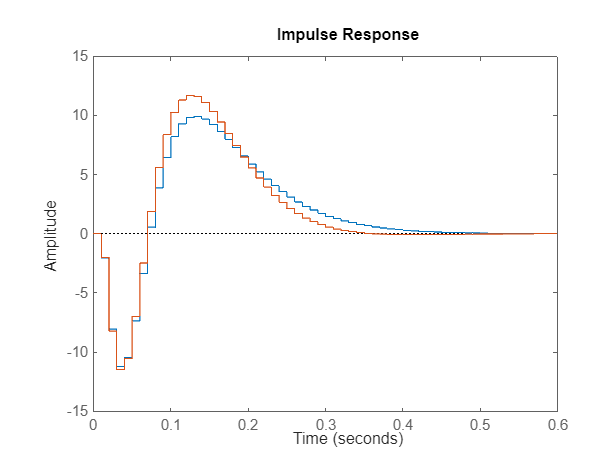

% Comparing responses
impulse(Gz,Gt)

As we can see the response of the tweaked system slightly differs from the original system, especially during the overshoot and the settling regions, but the overall behaviour (in which we are interested in) does not change.

### 1.3. Extracting data from the system

If we get the data from a company, it is unlikely that they will give us the description of the system. Instead, what they will give us is the input and output measurements data. We need to extract from the system the data that we actually want to analyze. To do so we create a random vector of inputs, in order to stimulate the system, and a random vector of errors.

% Random inputs
U = randn(Nmax,1);

% Random errors
E = randn(Nmax,1);

We start by considering the variance of the noise equal to zero, meaning that our system will not be affected by noise (ideal case).

NoiseVariance = 0;

Then we use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the polynomials of the previously-tweaked system. MATLAB will automatically recognize the ARX model and all its parameters.

% System declaration
S = idpoly(A,B,[],[],[],NoiseVariance,Ts)

S =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)              
  A(z) = 1 - 2.61 z^-1 + 2.49 z^-2 - 1.02 z^-3 + 0.15 z^-4
                                                          
  B(z) = -0.02 z^-1 - 0.03 z^-2 + 0.05 z^-3 + 0.01 z^-4   
                                                          
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


Now we can finally simulate the behaviour of the system given the random input vector and the random error vector. Since we specified that the variance of the noise is equal to zero, MATLAB will assume that there is no uncertainty, realizing a deterministic model.

% Output vector
Y = sim(S,[U,E]);

Let's also plot the input and the output of the system.

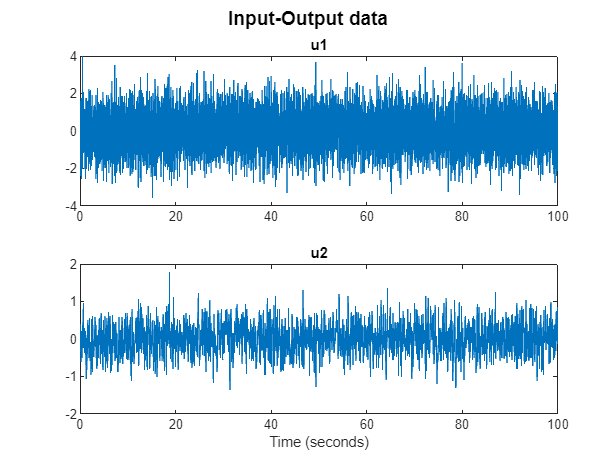

% Plotting data
figure(2),
subplot(2,1,1), plot(t,U), title("u1"),
subplot(2,1,2), plot(t,Y), title("u2"),
sgtitle("Input-Output data","FontWeight","Bold")
xlabel("Time (seconds)")

It is easy to see that the input and the output are very nervous and never reach the steady state. Also, output is slower than the input.

### 1.4. Splitting data in multiple sets

Since we now have our input and output measurement data, we can go on with the identification of the system.

We first create our `iddata` object, giving labels to the input and to the output.

% Creating data object
data = iddata(Y,U,Ts);

% Labeling
data.InputName = "Input";
data.OutputName = "Output";

In order to evaluate how the identification process changes with respect to the number of available data, we split our dataset into multiple sets. Then we use the last 500 samples of the dataset for the validation phase. In other words, this will help us understand how the results of the identification process change with respect to the increase of the dimension of the data.

% Training sets
data50  = data(1:50);
data100 = data(1:100);
data200 = data(1:200);
data500 = data(1:500);
datainf = data(1:9500);

% Validation set
validdata = data(9500:10000);

### 1.5. Identifying the system using ARX models

Let's declare different ARX models, one for each of the previously-splitted training sets, with 4 coefficients for each polynomial.

% ARX(4,4,1) models
m50  = arx( data50,[4,4,1]);
m100 = arx(data100,[4,4,1]);
m200 = arx(data200,[4,4,1]);
m500 = arx(data500,[4,4,1]);
minf = arx(datainf,[4,4,1]);

Then we extract the numerator and the denominator of each of the identified models in order to have an immediate comparison.

% Numerators and denominators
[ B50, A50] = tfdata( m50,'v');
[B100,A100] = tfdata(m100,'v');
[B200,A200] = tfdata(m200,'v');
[B500,A500] = tfdata(m500,'v');
[Binf,Ainf] = tfdata(minf,'v');

Then we compute the error as the maximum of the difference between the real parameters and the identified parameters.

% Parameters errors
err50  = max([ abs(B50-B), abs(A50-A)]);
err100 = max([abs(B100-B), abs(A100-A)]);
err200 = max([abs(B200-B), abs(A200-A)]);
err500 = max([abs(B500-B), abs(A500-A)]);
errinf = max([abs(Binf-B), abs(Ainf-A)]);

For the sake of simplicity we save all the errors in one vector.

param_err = [err50, err100, err200, err500, errinf];

Finally we also try to identify the system using a model that does not properly belong to the family of the system we want to identify.

In particular, the model is still an ARX model, but it has different parameters.

% Bad model
mbad = arx(data200,[4,3,1]);

### 1.6. Validating the estimated models

Once the training is done, we can go on with validation. We start by comparing the behaviour of all the models on the validation set.

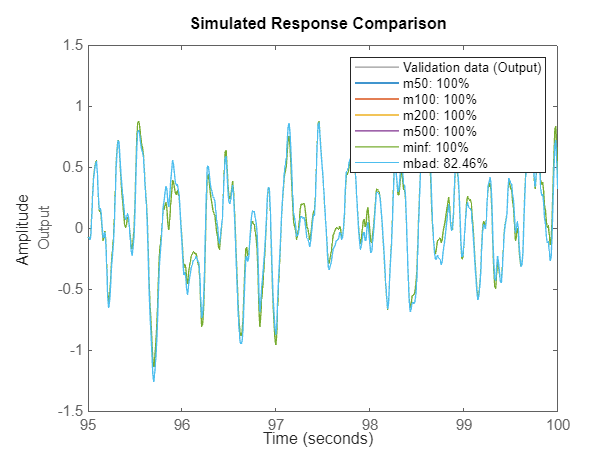

% Comparing models
figure(3),
compare(validdata,m50,m100,m200,m500,minf,mbad)

As we can see, all the models that belong to the same family of the system to be identified achieve a fit of 100%. This confirms the fact that, if the system belongs to the same family of the model chosen for the identification, for a number of data samples that goes to infinity, the estimated vector of parameters tends to the true vector of parameters, meaning that the identified model will be perfect.

That is not the case for the wrong model, which does not belong to the same family of the system to be identified. As a matter of fact, the fit of the wrong model is not equal to 100%, though it is still acceptable.

### 1.7. Comparing and understanding results

We can better visualize what happened during the identification process by plotting the errors and the fits with respects to the number of data samples. First we need to extract the estimated output and the values of the fit function for each of the considered models.

% Extracting data
[~,FIT,~] = compare(validdata,m50,m100,m200,m500,minf);

Then we plot the errors and the fit functions with respect to the number of data samples.

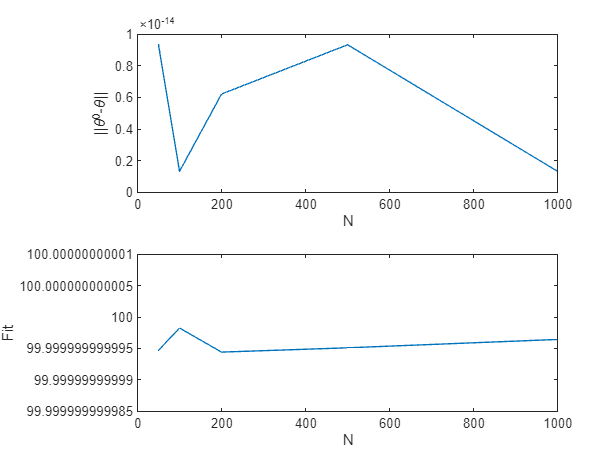

% Plotting comparisons
figure(4),
subplot(2,1,1),
plot([50,100,200,500,1000],param_err),
xlabel("N"), ylabel("||\theta^0-\theta||"),
subplot(2,1,2),
plot([50,100,200,500,1000],cell2mat(FIT)),
xlabel("N"), ylabel("Fit")

As we can see, the error is always very low but it decreases as the number of data samples increases. Same stands for the fit values.

### 1.8. Considering uncertainty in the system

The previous results were perfect because not only we used ARX models belonging to the same family of the system to be identified, but also because the variance of the noise was equal to zero so there was no uncertainty. Let us now consider a proper value for the variance of the noise, for example `1e-4`, in order to introduce a small amount of white noise into the system.

% Noise variance
NoiseVariance = 1e-4;

We repeat the same process as before.

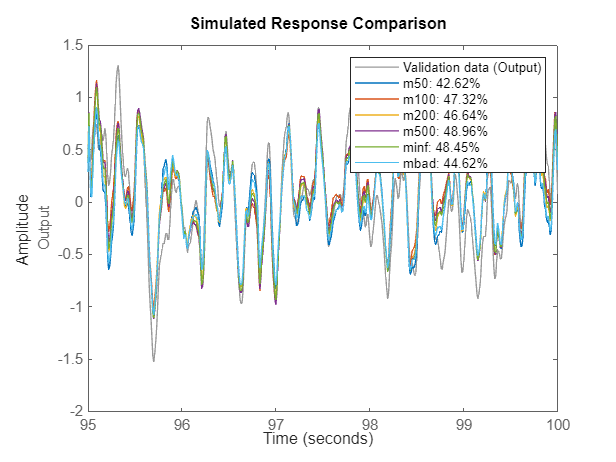

% System declaration
S = idpoly(A,B,[],[],[],NoiseVariance,Ts);

% Output vector
Y = sim(S,[U,E]);

% Creating data object
data = iddata(Y,U,Ts);

% Labeling data object
data.InputName = "Input";
data.OutputName = "Output";

% Training sets
data50  = data(1:50);
data100 = data(1:100);
data200 = data(1:200);
data500 = data(1:500);
datainf = data(1:9500);

% Validation set
validdata = data(9500:10000);

% ARX(4,4,1) models
m50  = arx( data50,[4,4,1]);
m100 = arx(data100,[4,4,1]);
m200 = arx(data200,[4,4,1]);
m500 = arx(data500,[4,4,1]);
minf = arx(datainf,[4,4,1]);

% Numerators and denominators
[ B50, A50] = tfdata( m50,'v');
[B100,A100] = tfdata(m100,'v');
[B200,A200] = tfdata(m200,'v');
[B500,A500] = tfdata(m500,'v');
[Binf,Ainf] = tfdata(minf,'v');

% Parameters errors
err50  = max([ abs(B50-B), abs(A50-A)]);
err100 = max([abs(B100-B), abs(A100-A)]);
err200 = max([abs(B200-B), abs(A200-A)]);
err500 = max([abs(B500-B), abs(A500-A)]);
errinf = max([abs(Binf-B), abs(Ainf-A)]);
param_err = [err50, err100, err200, err500, errinf];

% Bad model
mbad = arx(data200,[4,3,1]);

% Comparing models
figure(5),
compare(validdata,m50,m100,m200,m500,minf,mbad)

Before we had 100% fit for all of our models because the variance of the noise was set equal to zero, so there was no uncertainty. This time, noise led to lower values of the fit. Still we can say that, by increasing the number of data samples, the fit also increases.

We can better assess the described behaviour by plotting the error and the fit with respect to the number of data samples.

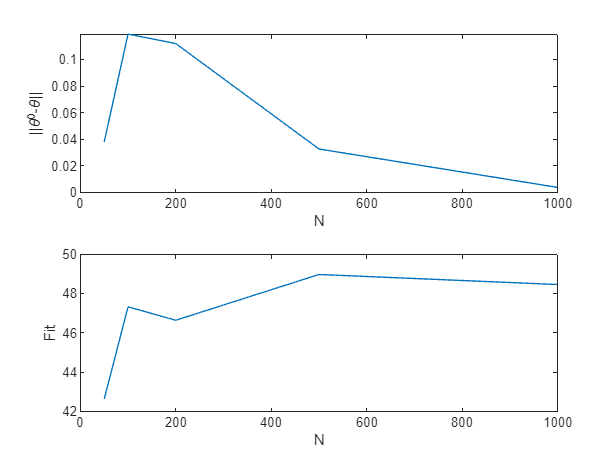

% Extracting data
[~,FIT,~] = compare(validdata,m50,m100,m200,m500,minf);

% Plotting comparisons
figure(6),
subplot(2,1,1),
plot([50,100,200,500,1000],param_err),
xlabel("N"), ylabel("||\theta^0-\theta||"),
subplot(2,1,2),
plot([50,100,200,500,1000],cell2mat(FIT)),
xlabel("N"), ylabel("Fit")

As said before, the error decreases when the number of data samples increases while the fit increases.

### 1.9. Prediction error analysis

In order to further evaluate the performances of our models, here we perform a whiteness test. A model is considered to be good if the autocorrelation function of the prediction error and the cross-correlation function between the input and the prediction error are bounded withing the traced confidence intervals. In order to have whiteness in the prediction error, the autocorrelation function should be impulsive (meaning that each sample is only correlated to itself) while the crosscorrelation should be always zero.

For example, we consider the model identified over the training set composed by 50 data samples.

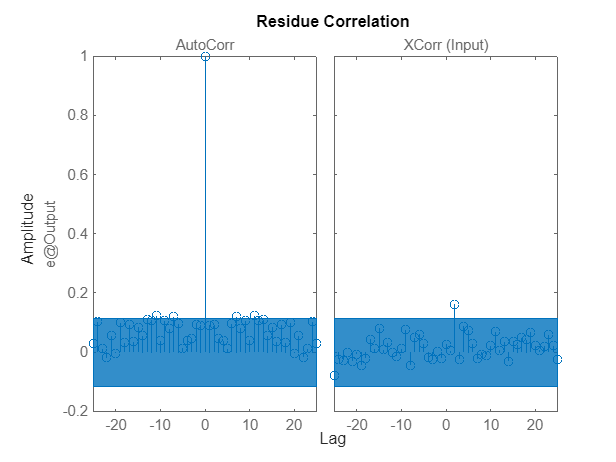

% Whiteness test
figure(7), resid(m50,validdata,'corr')

As we can see, the cross-correlation is not always bounded. Let's also have a look at the impulse response of this model.

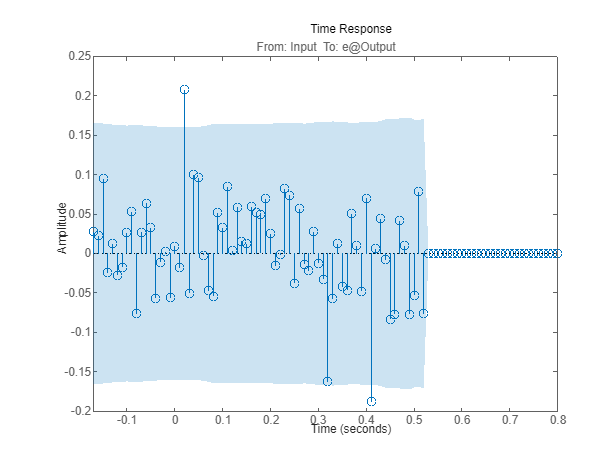

% Prediction error
E = resid(m50,validdata);
figure(8), impulse(E,'sd',3); 

Let us now consider the identified model that does not belong to the family of the system.

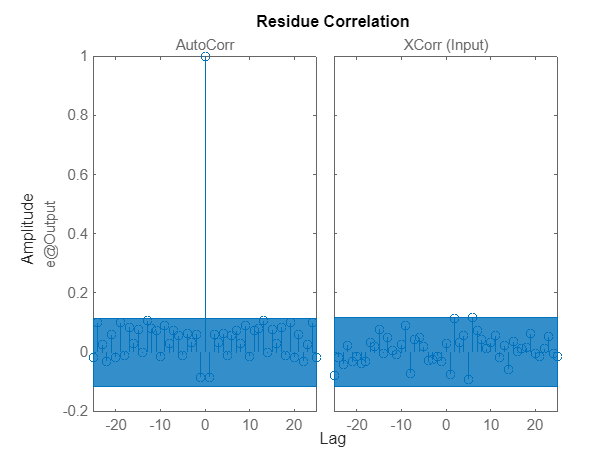

% Whiteness test
figure(9), resid(mbad,validdata,'corr')

The behaviour of this model, just like the value of the fit, is more or less comparable.

## 2. Identifying an ARMAX system with an ARMAX model

We now want to estimate an ARMAX system using an ARMAX model, in order to show that the estimation error will always decrease when we progressively increase the size of the dataset used for training the model.

clc, clearvars, close all

### 2.1. Generating the system to identify

We choose the sampling time, we create the time vector and we retrieve the maximum dimension of data.

% Sampling time
Ts = 0.01;

% Time vector
t = (0:Ts:(10000*Ts))';

% Data dimension
Nmax = length(t);

Then we generate the system we want to identify using the `zpk` function, which return the continuous transfer function of the system by giving in input the zeros, the poles and the static gain of the system.

% Continuous transfer function
G = zpk(10, [-20, -20, -50, -100], -400*50*10);

Since the data acquisition process is discrete, we need to discretize the transfer function of the system.

% Discretization of the transfer function
Gz = c2d(G,Ts);

Let's see how the discrete system behaves through its impulse response.

% Impulse response
figure(1), impulse(Gz)

We can see a negative peak at the beginning of the impulse response, which is a typical behaviour in non-minimal phase systems, i.e. systems with a positive zero (indeed we have 10 as a zero). We also notice that there is a small delay between the input and the output and that there is an important overshoot that goes to steady state after a few time instants.

### 2.2. Tweaking the parameters of the system

We extract the numerator and denominator coefficients from the transfer function using the command `tfdata`.

% Extracting coefficients
[num,den] = tfdata(Gz,'v')

num =          0   -0.0204   -0.0273    0.0476    0.0083


den =     1.0000   -2.6119    2.4890   -1.0185    0.1496


Then we tweak the parameters of the system rounding them up in order to better appreciate the quality of the estimates.

% Rounding coefficients
B = [0.00, -0.02, -0.03,  0.05, 0.01];
A = [1.00, -2.61,  2.49, -1.02, 0.15];

In this case we also introduce the parameters of the third polynomial `C`.

% Third degree-of-freedom polynomial
C = [1.00, 1.90, 0.40];

With those vectors, MATLAB will consider the system as an ARMAX(4,4,2,1).

% Transfer function
Gt = tf(B,A,Ts);

Let's compare the impulse response of the tweaked system and of the initial system.

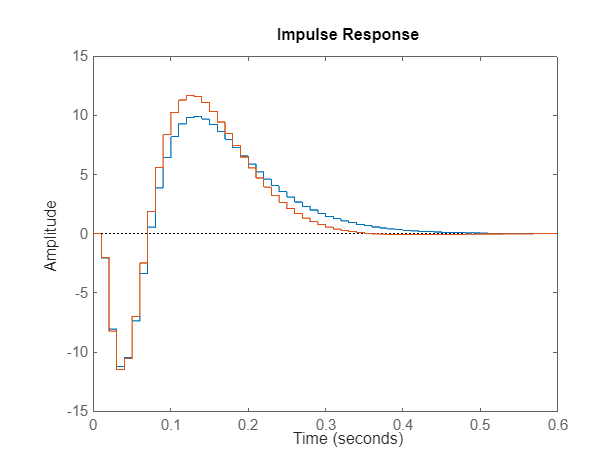

% Comparing responses
impulse(Gz,Gt)

As we can see the response of the tweaked system slightly differs from the original system, especially during the overshoot and the settling regions, but the overall behaviour (in which we are interested in) does not change.

### 2.3. Extracting data from the system

We need to extract again from the system the data that we actually want to analyze.

To do so we create a random vector of inputs, in order to stimulate the system, and a random vector of errors.

% Random inputs
U = randn(Nmax,1);

% Random errors
E = randn(Nmax,1);

We consider a small variance of the error, in order to introduce a vert light noise in the system.

NoiseVariance = 1e-7;

Then we use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the polynomials of the previously-tweaked system. MATLAB will automatically recognize the ARMAX model and all its parameters.

% System declaration
S = idpoly(A,B,C,[],[],NoiseVariance,Ts)

S =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t) 
  A(z) = 1 - 2.61 z^-1 + 2.49 z^-2 - 1.02 z^-3 + 0.15 z^-4
                                                          
  B(z) = -0.02 z^-1 - 0.03 z^-2 + 0.05 z^-3 + 0.01 z^-4   
                                                          
  C(z) = 1 + 1.9 z^-1 + 0.4 z^-2                          
                                                          
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=2   nk=1
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 


Now we can finally simulate the behaviour of the system given the random input vector and the random error vector.

% Output vector
Y = sim(S,[U,E]);

### 2.4. Splitting data in multiple sets

Since we now have our input and output measurement data, we can go on with the identification of the system.

We first create our `iddata` object, giving labels to the input and to the output.

% Creating data object
data = iddata(Y,U,Ts);

% Labeling
data.InputName = "Input";
data.OutputName = "Output";

In order to evaluate how the identification process changes with respect to the number of available data, we split our dataset into multiple sets. Then we use the last 500 samples of the dataset for the validation phase. In other words, this will help us understand how the results of the identification process change with respect to the increase of the dimension of the data.

% Training sets
data50  = data(1:50);
data500 = data(1:500);
datainf = data(1:9500);

% Validation set
validdata = data(9500:10000);

### 2.5. Identifying the system using ARMAX models

Let's declare different ARMAX models, one for each of the previously-splitted training sets.

% ARXMAX(4,4,2,1) models
m50  = armax(data50,[4,4,2,1]);
m500 = armax(data500,[4,4,2,1]);
minf = armax(datainf,[4,4,2,1]);

### 2.6. Validating the estimated models

Once the training is done, we can go on with validation. We start by comparing the behaviour of all the models on the validation set.

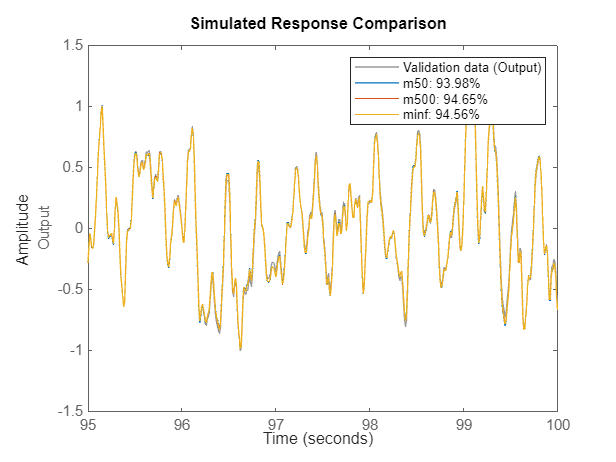

% Comparing models
figure(2),
compare(validdata,m50,m500,minf)

As we can see, the results are good but the fit is never equal to 100% because of the uncertainty.

### 2.7. Prediction error analysis

We now perform the whiteness test for each of the identified models. Let's consider the first model `m50`.

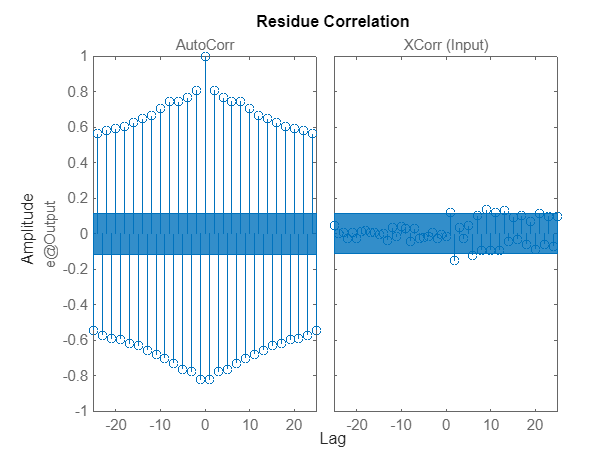

% Whiteness test
figure(3), resid(m50,validdata)

The autocorrelation function is not impulsive and the cross-correlation is not bounded. Let's consider the second model `m500`.

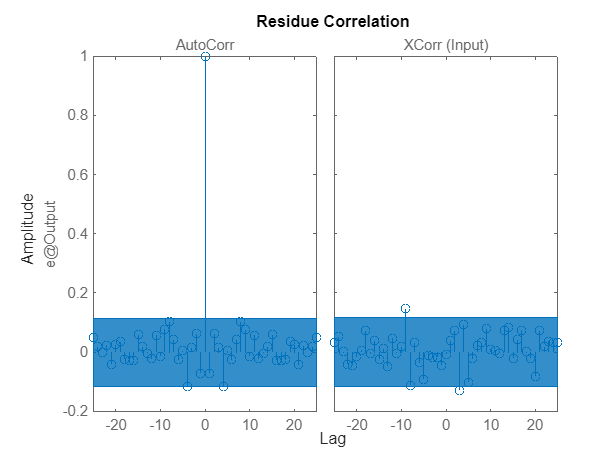

% Whiteness test
figure(4), resid(m500,validdata)

The autocorrelation is now impulsive because the number of data samples is quite high. Let's also consider the third model `minf`.

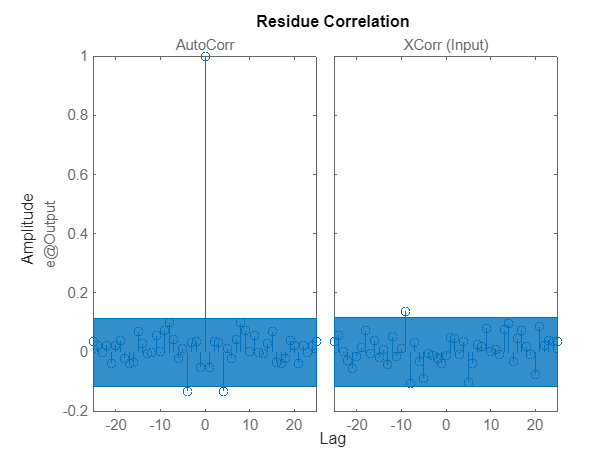

% Whiteness test
figure(5), resid(minf,validdata)

Of course in this case we have a perfect whiteness test. Finally, let's plot the impulse response of the error for the model `m500`.

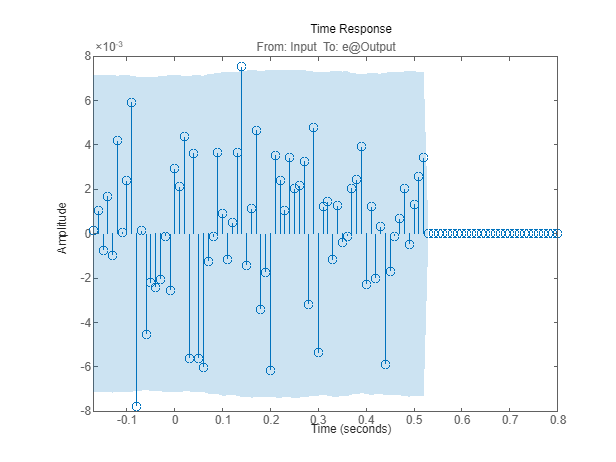

% Prediction error
E = resid(m500,validdata);
figure(6), impulse(E,'sd',3); 

The uncertainty band is very high, though the response is always bounded.

### 2.8. Comparing and understanding results

We can better visualize what happened during the identification process by plotting the errors with respects to the number of data samples. First we need to extract the polynomials of each of the identified models. Let us remember that now, along with the polynomials `A` and `B`, we also have to consider the polynomial `C` which is related to the error.

% Numerators and denominators
A50  =  m50.A; B50  =  m50.B; C50  =  m50.C;
A500 = m500.A; B500 = m500.B; C500 = m500.C;
Ainf = minf.A; Binf = minf.B; Cinf = minf.C;

Then we compute the error as the norm of the difference between the real parameters and the identified parameters.

% Parameters errors
errA = [norm(A50-A), norm(A500-A), norm(Ainf-A)];
errB = [norm(B50-B), norm(B500-B), norm(Binf-B)];
errC = [norm(C50-C), norm(C500-C), norm(Cinf-C)];

Finally we plot the error for each of the polynomials with respect to the number of data samples.

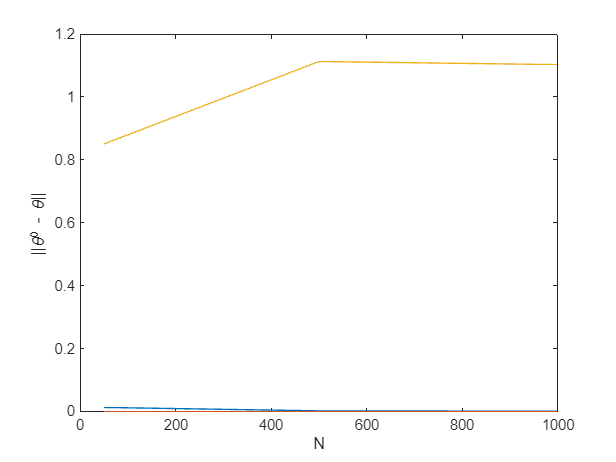

% Plotting errors
figure(7),
plot([50, 500, 1000], errA), hold on,
plot([50, 500, 1000], errB), hold on,
plot([50, 500, 1000], errC), hold off,
xlabel("N"), ylabel("||\theta^0 - \theta||")

As we can see, the error on the polynomial `C` is bigger due to the fact that it is directly related to the error.

## 3. Identifying an ARMAX system with an ARX model

We finally want to estimate an ARMAX system using an ARX model, in order to show how the identification deteriorates and how the error will not always decrease because the system does not belong to the family of the model chosen for the identification.

clc, clearvars, close all

### 3.1. Generating the system to identify

We choose the sampling time, we create the time vector and we retrieve the maximum dimension of data.

% Sampling time
Ts = 0.01;

% Time vector
t = (0:Ts:(10000*Ts))';

% Data dimension
Nmax = length(t)

Nmax = 10001

Then we generate the system we want to identify using the `zpk` function, which return the continuous transfer function of the system by giving in input the zeros, the poles and the static gain of the system.

% Continuous transfer function
G = zpk(10, [-20, -20, -50, -100], -400*50*10);

Since the data acquisition process is discrete, we need to discretize the transfer function of the system.

% Discretization of the transfer function
Gz = c2d(G,Ts);

Let's see how the discrete system behaves through its impulse response.

% Impulse response
figure(1), impulse(Gz)

We can see a negative peak at the beginning of the impulse response, which is a typical behaviour in non-minimal phase systems, i.e. systems with a positive zero (indeed we have 10 as a zero). We also notice that there is a small delay between the input and the output and that there is an important overshoot that goes to steady state after a few time instants.

### 3.2. Tweaking the parameters of the system

We extract the numerator and denominator coefficients from the transfer function using the command `tfdata`.

% Extracting coefficients
[num,den] = tfdata(Gz,'v')

num =          0   -0.0204   -0.0273    0.0476    0.0083


den =     1.0000   -2.6119    2.4890   -1.0185    0.1496


Then we tweak the parameters of the system rounding them up in order to better appreciate the quality of the estimates.

% Rounding coefficients
B = [0.00, -0.02, -0.03,  0.05, 0.01];
A = [1.00, -2.61,  2.49, -1.02, 0.15];

In this case we also introduce the parameters of the third polynomial `C`.

% Third degree-of-freedom polynomial
C = [1.00, 1.90, 0.40];

With those vectors, MATLAB will consider the system as an ARMAX(4,4,2,1).

% Transfer function
Gt = tf(B,A,Ts);

Let's compare the impulse response of the tweaked system and of the initial system.

% Comparing responses
impulse(Gz,Gt)

As we can see the response of the tweaked system slightly differs from the original system, especially during the overshoot and the settling regions, but the overall behaviour (in which we are interested in) does not change.

### 3.3. Extracting data from the system

We need to extract again from the system the data that we actually want to analyze.

To do so we create a random vector of inputs, in order to stimulate the system, and a random vector of errors.

% Random inputs
U = randn(Nmax,1);

% Random errors
E = randn(Nmax,1);

We consider a small variance of the error, in order to introduce a vert light noise in the system.

NoiseVariance = 1e-7;

Then we use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the polynomials of the previously-tweaked system. MATLAB will automatically recognize the ARMAX model and all its parameters.

% System declaration
S = idpoly(A,B,C,[],[],NoiseVariance,Ts)

S =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t) 
  A(z) = 1 - 2.61 z^-1 + 2.49 z^-2 - 1.02 z^-3 + 0.15 z^-4
                                                          
  B(z) = -0.02 z^-1 - 0.03 z^-2 + 0.05 z^-3 + 0.01 z^-4   
                                                          
  C(z) = 1 + 1.9 z^-1 + 0.4 z^-2                          
                                                          
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=2   nk=1
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 


Now we can finally simulate the behaviour of the system given the random input vector and the random error vector.

% Output vector
Y = sim(S,[U,E]);

### 3.4. Splitting data in multiple sets

Since we now have our input and output measurement data, we can go on with the identification of the system.

We first create our `iddata` object, giving labels to the input and to the output.

% Creating data object
data = iddata(Y,U,Ts);

% Labeling
data.InputName = "Input";
data.OutputName = "Output";

In order to evaluate how the identification process changes with respect to the number of available data, we split our dataset into multiple sets. Then we use the last 500 samples of the dataset for the validation phase. In other words, this will help us understand how the results of the identification process change with respect to the increase of the dimension of the data.

% Training sets
data50  = data(1:50);
data500 = data(1:500);
datainf = data(1:9500);

% Validation set
validdata = data(9500:10000);

### 3.5. Identifying the system using ARX models

Let's declare different ARX models, one for each of the previously-splitted training sets.

% ARXMAX(4,4,2,1) models
m50  = arx( data50,[4,4,1]);
m500 = arx(data500,[4,4,1]);
minf = arx(datainf,[4,4,1]);

### 3.6. Validating the estimated models

Once the training is done, we can go on with validation. We start by comparing the behaviour of all the models on the validation set.

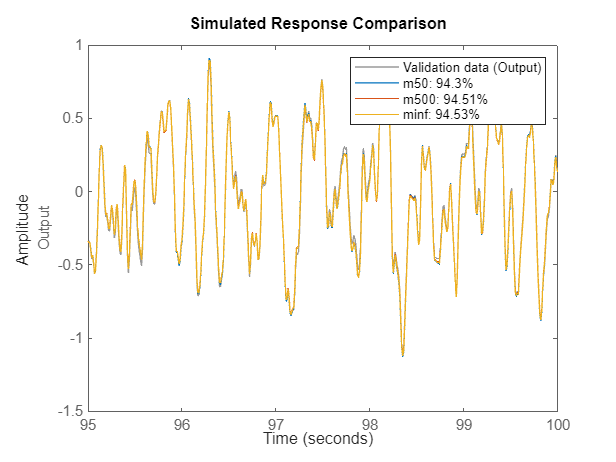

% Comparing models
figure(2),
compare(validdata,m50,m500,minf)

As we can see, the results are still good.

### 3.7. Prediction error analysis

We now perform the whiteness test for each of the identified models. Let's consider the first model `m50`.

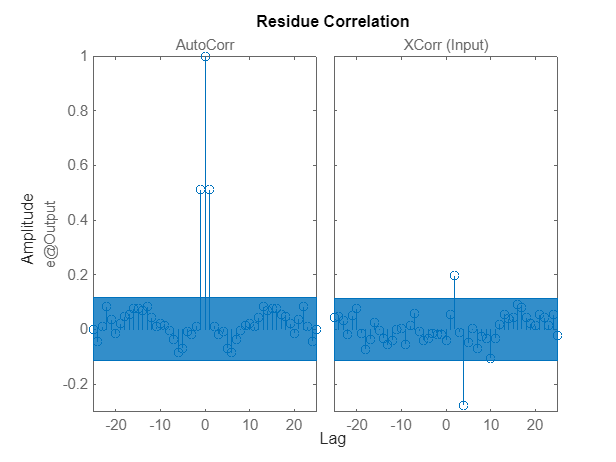

% Whiteness test
figure(3), resid(m50,validdata)

The autocorrelation function is not impulsive and the cross-correlation is not bounded. Let's consider the second model `m500`.

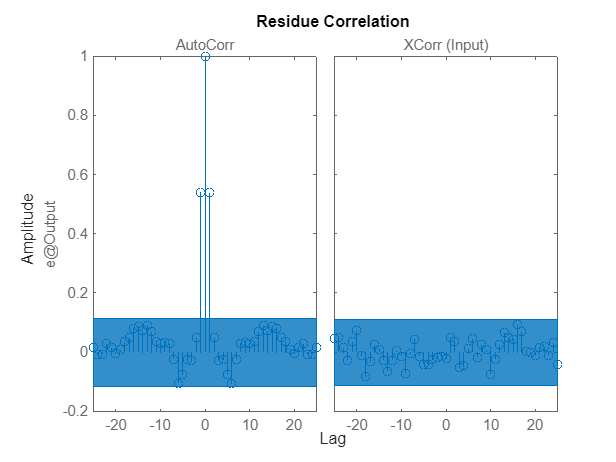

% Whiteness test
figure(4), resid(m500,validdata)

The autocorrelation is now semi-impulsive because the number of data samples is quite high. Let's also consider the third model `minf`.

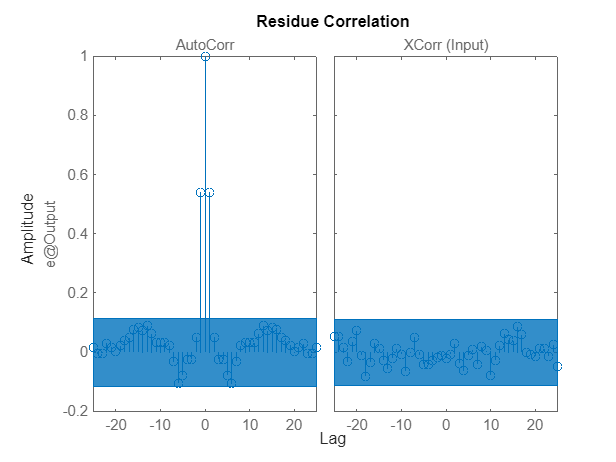

% Whiteness test
figure(5), resid(minf,validdata)

We can say the same things also on this model. Finally, let's plot the impulse response of the error for the model `m500`.

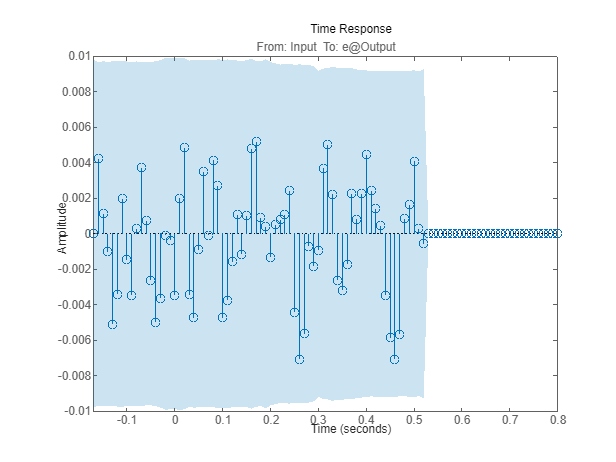

% Prediction error
E = resid(m500,validdata);
figure(6), impulse(E,'sd',3); 

The uncertainty band is very high, though the response is not always bounded.

### 3.7. Comparing and understanding results

We can better visualize what happened during the identification process by plotting the errors with respects to the number of data samples. First we need to extract the polynomials of each of the identified models. Let us remember that now we do not have an estimate of the polynomial `C` anymore, meaning that its error (if we know the true system) will be constant.

% Numerators and denominators
A50  =  m50.A; B50  =  m50.B;
A500 = m500.A; B500 = m500.B;
Ainf = minf.A; Binf = minf.B;

Then we compute the error as the norm of the difference between the real parameters and the identified parameters.

% Parameters errors
errA = [norm(A50-A), norm(A500-A), norm(Ainf-A)];
errB = [norm(B50-B), norm(B500-B), norm(Binf-B)];

Finally we plot the error for each of the polynomials with respect to the number of data samples.

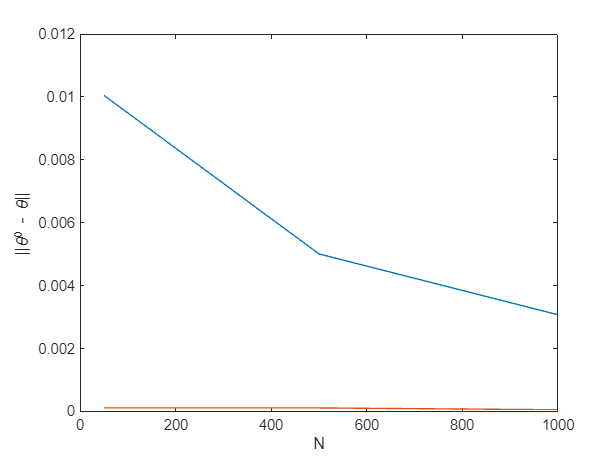

% Plotting errors
figure(7),
plot([50, 500, 1000], errA), hold on,
plot([50, 500, 1000], errB), hold off,
xlabel("N"), ylabel("||\theta^0 - \theta||")

As we can see the errors are very small, but we have to keep in mind that the error on the polynomial `C` is always equal to 1.

This constant behaviour of the error tells us there is something wrong with the identification process.